clc;clear;

x=0:100;
h_theta_C= 0.683244693421396.*x+0.0194232687228709;
h_theta_A=0.533618308019385.*x+10.0900788187966;
plot(x,h_theta_C,'r',x,h_theta_A,'b')
hold on
fc=@(x) 0.683244693421396*x+0.0194232687228709;
f=@(x) 0.683244693421396*x+0.0194232687228709-(0.533618308019385*x+10.0900788187966);
solx=fzero(f,70)

solx =           67.3053453975797


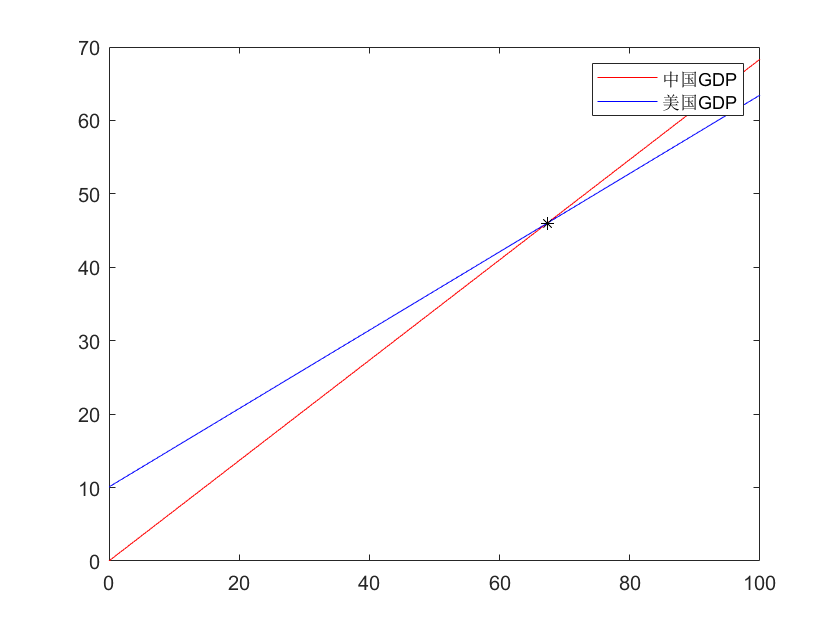

plot(solx,fc(solx),'k*')
legend('中国GDP','美国GDP')

fprintf('中国的GDP将于%d年超越美国',2000+round(solx))

中国的GDP将于2067年超越美国